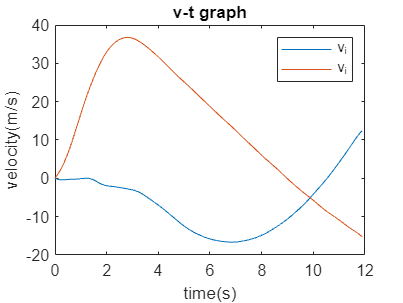

clc; clear; close all; format compact;
CleanedData = struct2array(load('Cleaned Acceleration Data.mat'));
% time  ax  ay  az  omega_x  omega_y  omega_z


t = CleanedData(:,1); %s
ax_b = CleanedData(:,2); %m/s^2
ay_b = CleanedData(:,3);
az_b = CleanedData(:,4);
%omega_x_b = CleanedData(:,5); %rad/s
omega_y_b = CleanedData(:,6); %rad/s
%omega_z_b = CleanedData(:,7);

theta_y = cumtrapz(t,omega_y_b); %rad


A_i = zeros(3,length(t));
for ctr = 1:length(t)
    R=[cos(theta_y(ctr))     0    -sin(theta_y(ctr));
         0              1           0;
       sin(theta_y(ctr))        0      cos(theta_y(ctr))]; %flight path to inertial
    A_b = [ax_b(ctr);
           ay_b(ctr);
           az_b(ctr);];
    A_i(:,ctr) = R'*A_b;
end

a_x_i = A_i(1,:); %m/s^2
a_y_i = A_i(2,:);
a_z_i = A_i(3,:);



v_x_i = cumtrapz(t,a_x_i);
v_z_i = cumtrapz(t,a_z_i);

x_i = cumtrapz(t,v_x_i);
z_i = cumtrapz(t,v_z_i);


figure
plot(t,v_x_i,t,v_z_i)
xlabel('time(s)');ylabel('velocity(m/s)');title('v-t graph')
legend('v_x_,_i','v_z_,_i')

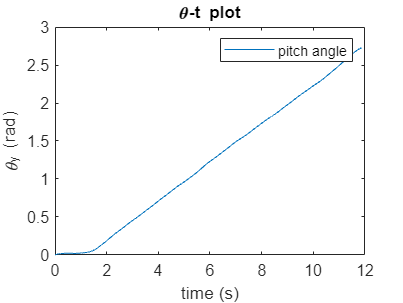

figure
plot(t,theta_y); xlabel('time (s)'); ylabel('\theta_y (rad)'); title('\theta-t plot')
legend('pitch angle')

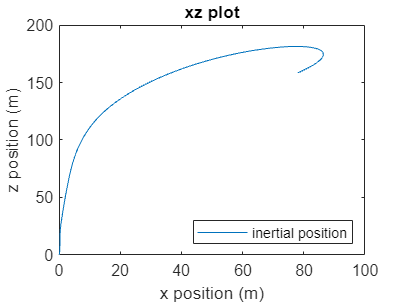

figure
plot(-x_i,z_i); xlabel('x position (m)'); ylabel('z position (m)'); title('xz plot') %x is negative for some reason
legend('inertial position','location','southeast')

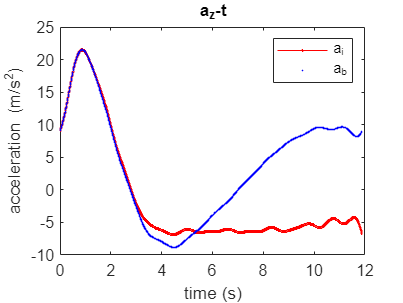

figure;
plot(t,a_z_i,'r-d',t,az_b,'b.',MarkerSize=1); xlabel('time (s)'); ylabel('acceleration (m/s^2)'); title('a_z-t')
legend('a_z_,_i','a_z_,_b')

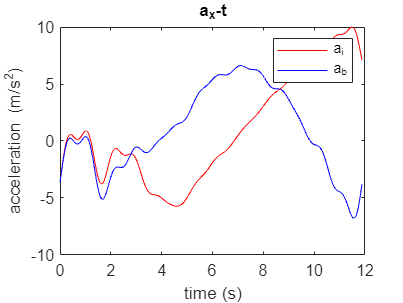

figure
plot(t,a_x_i,'r',t,ax_b,'b'); xlabel('time (s)'); ylabel('acceleration (m/s^2)'); title('a_x-t')
legend('a_x_,_i','a_x_,_b')